clear global;
close all;
clc;
clf;

% Parameters 
aspace = linspace(5,15,6); 
sspace = linspace(1,50,15); 

p = 0.1;                % dollars per bushel
Y = 12500;              % yield
d = 0.25;               % damage proportion
K = 50;                 % CC for the farm
r = 0.584;              % growth rate
c1 = 130;                % variable cost
c0 = 100;               % fixed cost
delta = 0.1;            % discount rate
s1 = 600;               % fixed farming cost
mu = 0.1;               % variable farming cost based on hog damage
a  = 1;                  % avoidance
beta = 2;               % damage intensity
sstar=[0,0,0,0]

sstar =      0     0     0     0


optimal_harvest=[0,0,0,0]

optimal_harvest =      0     0     0     0


lam_val=[0,0,0,0,0,0];


for i= 1:4
 s1  = sseq(i);

% Define the ftrfun function
ftrfun = @(s) (-p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - s1*mu/K + a*c1*r*s*(1-s/K)./(s.^2)) ...
               ./ (p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - a*c1./s) + r - 2*r*s/K - delta;

% Vector of population values
s = linspace(0.001, K, 100);

% Evaluate the function over the population values
ssval = arrayfun(ftrfun, s);

% Finding the steady state
sstar(i) = fzero(ftrfun, [10, 50])

% Solving the appropriate x to match the population
xstar = r * sstar(i) * (1 - sstar(i) / K);

% Define the hfind function
hfind = @(h) (-p*d*beta*((sstar(i)-h).^(beta-1)) - s1*mu/K + a*c1*h/(sstar(i)^2)) ...
              ./ (p*d*beta*((sstar(i)-h).^(beta-1)) - a*c1/sstar(i)) + r - 2*r*sstar(i)/K - delta;

% Finding the optimal harvest value
optimal_harvest(i) = fzero(hfind, [0.01, 20])

end

Unrecognized function or variable 'sseq'.

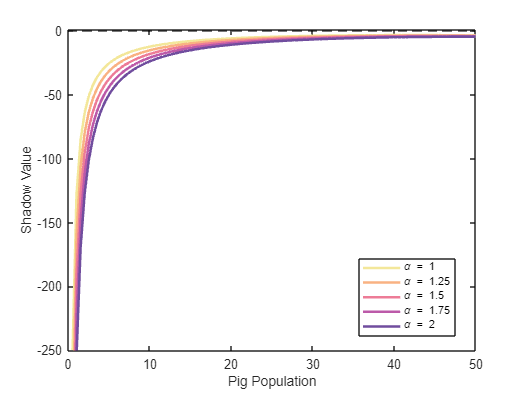


close all;
clf;
s = linspace(0.001, K, 100);
aspace= [1, 1.25, 1.5, 1.75, 2];
lam1 = @(s) (r*(1 - s/K) - (s*r)/K + 1) .* (2*d*p*(s - r*s.*(1 - s/K)) - (aspace(1)*c1)./s) + ...
           (aspace(1)*c1*r*s.*(1 - s/K))./s.^2 - 2*d*p*(s - r*s.*(1 - s/K)) - (mu*s1)/K;
lamval1 = arrayfun(lam1, s);

lam2 = @(s) (r*(1 - s/K) - (s*r)/K + 1) .* (2*d*p*(s - r*s.*(1 - s/K)) - (aspace(2)*c1)./s) + ...
           (aspace(2)*c1*r*s.*(1 - s/K))./s.^2 - 2*d*p*(s - r*s.*(1 - s/K)) - (mu*s1)/K;
lamval2 = arrayfun(lam2, s);

lam3 = @(s) (r*(1 - s/K) - (s*r)/K + 1) .* (2*d*p*(s - r*s.*(1 - s/K)) - (aspace(3)*c1)./s) + ...
           (aspace(3)*c1*r*s.*(1 - s/K))./s.^2 - 2*d*p*(s - r*s.*(1 - s/K)) - (mu*s1)/K;
lamval3 = arrayfun(lam3, s);

lam4 = @(s) (r*(1 - s/K) - (s*r)/K + 1) .* (2*d*p*(s - r*s.*(1 - s/K)) - (aspace(4)*c1)./s) + ...
           (aspace(4)*c1*r*s.*(1 - s/K))./s.^2 - 2*d*p*(s - r*s.*(1 - s/K)) - (mu*s1)/K;
lamval4 = arrayfun(lam4, s);

lam5 = @(s) (r*(1 - s/K) - (s*r)/K + 1) .* (2*d*p*(s - r*s.*(1 - s/K)) - (aspace(5)*c1)./s) + ...
           (aspace(5)*c1*r*s.*(1 - s/K))./s.^2 - 2*d*p*(s - r*s.*(1 - s/K)) - (mu*s1)/K;
lamval5 = arrayfun(lam5, s);

colors = [
    112, 77, 158;  % #704D9E
    188, 90, 169;  % #BC5AA9
    237, 124, 151; % #ED7C97
    249, 178, 130; % #F9B282
    243, 231, 154  % #F3E79A
] / 255;  % Convert to MATLAB RGB scale

% Plot data with custom colors
figure;
plot(s, lamval1, 'LineWidth', 2, 'Color', colors(5,:));
hold on;
plot(s, lamval2, 'LineWidth', 2, 'Color', colors(4,:));
plot(s, lamval3, 'LineWidth', 2, 'Color', colors(3,:));
plot(s, lamval4, 'LineWidth', 2, 'Color', colors(2,:));
plot(s, lamval5, 'LineWidth', 2, 'Color', colors(1,:));
xlim([0, 50]);
ylim([-250, 1]);
yline(0, 'k--');
xlabel('Pig Population');
ylabel('Shadow Value');
legend('\alpha = 1', '\alpha = 1.25', '\alpha = 1.5', '\alpha = 1.75', '\alpha = 2', 'Location', 'best');
fname = strcat('lambda_over_pop_highcost.png') ;
saveas(gcf,fname)

figure;
plot(aspace, optimal_harvest, 'DisplayName', 'Optimal Harvest','LineWidth',2);

Error using plot
Vectors must be the same length.

hold on;
plot(aspace, sstar, 'DisplayName', 'Optimal Population','LineWidth',2);
xlabel('Avoidance Behavior');
ylabel('Hog Count')
legend('show', Location='northwest'); % Show the legend
%fname = strcat('aplha_N_H.png') ;
%saveas(gcf,fname)


figure;
plot(aspace, lam_val, 'LineWidth',2);
hold on;
xlabel('Avoidance Behavior');
ylabel('Shadow Value')
fname = strcat('shadow across avoid.png') ;
saveas(gcf,fname)


% Model structure
model.func = 'hogfunction';
model.discount = delta;
model.params = {p, d, K, r, c1, c0, s1, a, beta, Y, mu};

% Specifying basis function and collocation nodes
n = 25;
smin = 0.1;
smax = K;
fspace = fundefn('cheb', n, smin, smax); %Defines a function family structure
snodes = funnode(fspace);

% Initial guesses for values and actions at the collocation nodes. They
% used the steady state values, but ours is crazy looking an not simple
sstar = 10;
xstar = r*sstar*(1-sstar/K);
% pstar is the shadow price
pstar=-0.01;
[vlq, xlq, plq] = lqapprox(model, snodes, sstar, xstar,pstar);

% Solve the decision model
[c, s, v, x, resid] = dpsolve(model, fspace, snodes, vlq, xlq);

% Fundamental theorem of renewables resources equation with optimal s value
ssval =  ((r * (1 - s / K) - (s * r) / K + 1) .* ...
          (2 * d * p .* (s - s .* r .* (1 - s / K)) - (a * c1) ./ s) + ...
          (a * c1 * r .* (1 - s / K)) ./ s - ...
          2 * d * p .* (s - s .* r .* (1 - s / K)) - ...
          (mu * s1) / K) ./ ...
          (2 * d * p .* (s - s .* r .* (1 - s / K)) - (a * c1) ./ s) - 0.1 - 1;
optpop = s(knnsearch(ssval,0)) %finds the population index at the ssvalue closest to 0
optharv = x(knnsearch(ssval,0)) %finds the population index at the ssvalue closest to 0

close all;
clf;

figure;
plot(s, v,'k')
xlabel("Population");
ylabel("Net Benefit");



% Define the ftrfun function
d=0.15

d = 0.1500

ftrfun = @(s) (-p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - s1*mu/K + a*c1*r*s*(1-s/K)./(s.^2)) ...
               ./ (p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - a*c1./s) + r - 2*r*s/K - delta;

% Vector of population values
s = linspace(0.001, K, 100);

% Evaluate the function over the population values
ssval1 = arrayfun(ftrfun, s);

% Define the ftrfun function
d=0.25

d = 0.2500

ftrfun = @(s) (-p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - s1*mu/K + a*c1*r*s*(1-s/K)./(s.^2)) ...
               ./ (p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - a*c1./s) + r - 2*r*s/K - delta;

% Vector of population values
s = linspace(0.001, K, 100);

% Evaluate the function over the population values
ssval2 = arrayfun(ftrfun, s);

% Define the ftrfun function
d=0.45

d = 0.4500

ftrfun = @(s) (-p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - s1*mu/K + a*c1*r*s*(1-s/K)./(s.^2)) ...
               ./ (p*d*beta*((s-r*s*(1-s/K)).^(beta-1)) - a*c1./s) + r - 2*r*s/K - delta;

% Vector of population values
s = linspace(0.001, K, 100);

% Evaluate the function over the population values
ssval3 = arrayfun(ftrfun, s);

ssval3 =    -0.1000   -0.1012   -0.1023   -0.1034   -0.1044   -0.1053   -0.1060   -0.1067   -0.1073   -0.1077   -0.1080   -0.1081   -0.1080   -0.1078   -0.1074   -0.1068   -0.1060   -0.1049   -0.1036   -0.1020   -0.1002   -0.0980   -0.0955   -0.0926   -0.0894   -0.0858   -0.0818   -0.0773   -0.0724   -0.0669   -0.0609   -0.0542   -0.0470   -0.0391   -0.0304   -0.0210   -0.0108    0.0004    0.0125    0.0256    0.0399    0.0553    0.0721    0.0903    0.1101    0.1315    0.1548    0.1801    0.2076    0.2375


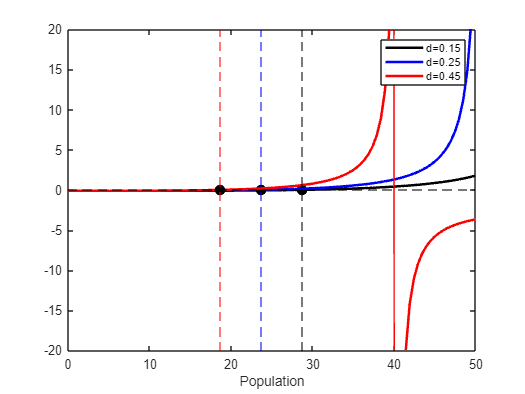


close all;
clf;

% Plotting the fundamental theorem of renewable resources
figure;
% Plot for ssval1 (black) d=0.25
h1 = plot(s, ssval1, 'k', 'LineWidth', 2); % Black line
hold on;
yline(0, 'k--'); % Black dashed line
xlabel("Population");
[~, idx] = min(abs(ssval1));
plot(s(idx), 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8); % Black circle
xline(s(idx), 'k--'); % Black vertical dashed line

% Plot for ssval2 (blue) d=0.35
h2 = plot(s, ssval2, 'b', 'LineWidth', 2); % Blue line
[~, idx] = min(abs(ssval2));
plot(s(idx), 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8); % Black circle
xline(s(idx), 'b--'); % Blue vertical dashed line

% Plot for ssval3 (red) d=0.45
h3 = plot(s, ssval3, 'r', 'LineWidth', 2); % Red line
[~, idx] = min(abs(ssval3));
plot(s(idx), 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8); % Black circle
xline(s(idx), 'r--'); % Red vertical dashed line
ylim([-20, 20]);

% Adding the legend for just the solid lines (h1, h2, h3)
legend([h1, h2, h3], {'d=0.15', 'd=0.25', 'd=0.45'}, 'Location', 'northeast');

hold off;

%fname = strcat('p_comp_matlab_a2_c20.png') ;
%saveas(gcf,fname)

plot(s, domval,'r','Linewidth',1.5)
%save plot
%fname = strcat('FTRR_a',num2str(a),'_vc',num2str(c1),'.png') ;
%saveas(gcf,fname)


% Finding the steady state
sstar = fzero(ftrfun, [1, 20])

sstar = 15.6082


% Solving the appropriate x to match the population
xstar = r * sstar * (1 - sstar / K);

% Define the hfind function
hfind = @(h) (-p*d*beta*((sstar-h).^(beta-1)) - s1*mu/K + a*c1*h/(sstar^2)) ...
              ./ (p*d*beta*((sstar-h).^(beta-1)) - a*c1/sstar) + r - 2*r*sstar/K - delta;

hfind = function_handle with value:
    @(h)(-p*d*beta*((sstar-h).^(beta-1))-s1*mu/K+a*c1*h/(sstar^2))./(p*d*beta*((sstar-h).^(beta-1))-a*c1/sstar)+r-2*r*sstar/K-delta



% Finding the optimal harvest value
optimal_harvest = fzero(hfind, [1, 50])

optimal_harvest = 6.2698


% Solution path
tmax = 100;          % Time
spath = zeros(1, tmax); % Population vector
xpath = zeros(1, tmax); % Harvest vector
sstartspace = [5,sstar,40];
lamval=zeros(1,tmax);

for w=1
spath(1) = sstartspace(w); % Initial population value: want to range this 
st = spath(1);
hfind = @(h) (-p*d*beta*((st-h).^(beta-1)) - s1*mu/K + a*c1*h/(st^2)) ...
                  ./ (p*d*beta*((st-h).^(beta-1)) - a*c1/st) + r - 2*r*st/K - delta;
xpath(1) =  fzero(hfind, [-1, 50]);

lam = @(s) (r*(1 - s/K) - (s*r)/K + 1) .* (2*d*p*(s - r*s.*(1 - s/K)) - (a*c1)./s) + ...
           (a*c1*r*s.*(1 - s/K))./s.^2 - 2*d*p*(s - r*s.*(1 - s/K)) - (mu*s1)/K;

lamval(1) = lam(st);

for i = 1:tmax-1
     spath(i+1) = spath(i) + r*spath(i)*(1-spath(i)/K) - xpath(i); % Growth equation
      st = spath(i+1);
      lamval(i+1) = lam(st);
    if spath(i+1) < 0
        spath(i+1) = 0 % Non-negativity constraint
    end
    if spath(i+1) ~= 0 
    hfind = @(h) (-p*d*beta*((st-h).^(beta-1)) - s1*mu/K + a*c1*h/(st^2)) ...
                  ./ (p*d*beta*((st-h).^(beta-1)) - a*c1/st) + r - 2*r*st/K - delta;
    xpath(i+1) = fzero(hfind, [-10, 10]);
    end
end
end


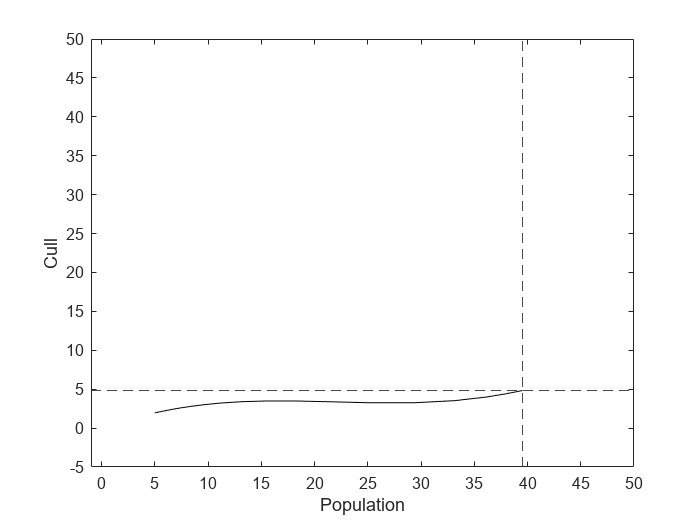


clf;
close all;
% Plot population vs harvest
figure;
plot(spath, xpath,'k' ,'LineWidth', 0.5);
xlim([-1, 50]);
ylim([-5, 50]);
xlabel('Population');
ylabel('Cull');
hold on;
xline(sstar, 'k--');
yline(xstar, 'k--');
hold off

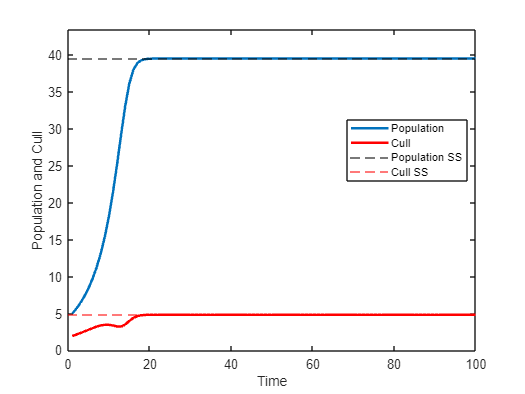

% Pause to ensure the plot is rendered (optional)
pause(1);

%save plot
%fname = strcat('cull_SSconv_a',num2str(a),'_vc',num2str(c1),'start',num2str(sstartspace(w)),'.png') ;
%saveas(gcf,fname)

close all;
clf;

% Plot spath and xpath over time
figure;
plot(1:tmax, spath, 'LineWidth', 2)
hold on;
plot(1:tmax, xpath, 'r', 'LineWidth', 2)
xlim([0, 100]);
ylim([0, max(spath)*1.1]);
xlabel('Time');
ylabel('Population and Cull');
yline(sstar, 'k--');
yline(xstar, 'r--');
legend('Population', 'Cull', 'Population SS', 'Cull SS', 'Location', 'best');

pause(1);


%save plot
%fname = strcat('cull_SSpath_a',num2str(a),'_vc',num2str(c1),'start',num2str(sstartspace(w)),'.png');
%saveas(gcf,fname)


% Plot spath and xpath over time
figure;
plot(1:tmax, lamval, 'LineWidth', 2)
xlabel('Time');
ylabel('Shadow Value');
pause(1);